**Physics 434: Application of Computers to Physical Measurement **

**11.21.19 (Entire Lab Due 12.08.19)**

**Author: Avi Soval **

**Collaborators: Jeff Jiang, Thomas Conaway **

#### **Lab 7: Event Selection Optimization for LHC Data **

**We continue our exploration of the LHC data with a strong QCD background. With our dedicated training sets of confirmed Higgs jets, we want to 'cut' or trim the background QCD data such that the signal-to-noise ratio for this background is maximized. **

h5disp("higgs_100000_pt_250_500.h5"); 

HDF5 higgs_100000_pt_250_500.h5 
Group '/' 
    Dataset 'higgs_100000_pt_250_500' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


h5disp('qcd_100000_pt_250_500.h5'); 

HDF5 qcd_100000_pt_250_500.h5 
Group '/' 
    Dataset 'qcd_100000_pt_250_500' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000



higgs = h5read("higgs_100000_pt_250_500.h5",'/higgs_100000_pt_250_500'); 
qcd = h5read("qcd_100000_pt_250_500.h5",'/qcd_100000_pt_250_500'); 

higgs = array2table(higgs,'RowNames',{'pt';'eta';'phi';'mass';'ee2';'ee3';'d2';'angularity';'t1';'t2';'t3';'t21';'t32';'KtDeltaR'}); 
qcd = array2table(qcd,'RowNames',{'pt';'eta';'phi';'mass';'ee2';'ee3';'d2';'angularity';'t1';'t2';'t3';'t21';'t32';'KtDeltaR'}); 

VariableNames = ["Transverse Momentum (GeV)";"Pseudorapidity";"Azimuthal Angle (rad)";"Invariant Mass";"2-Point ECF Ratio";"3-Point ECF Ratio";"3 to 2 Point ECF Ratio";"Angularity";"t1";"t2";"t3";"t21";"t32";"KtDeltaR"]; 

**First, we plot histograms of the Higgs and QCD invariant mass data, properly normalized to 1. **

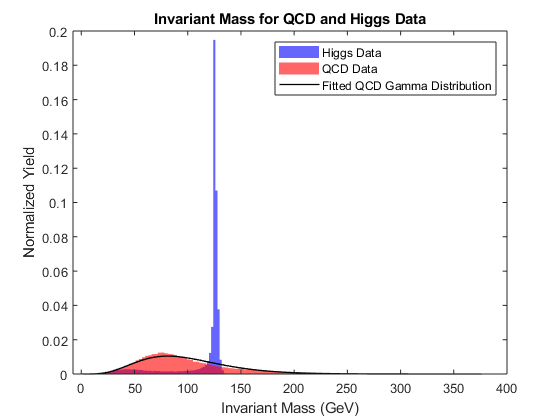

figure(1)
h1 = histogram(higgs{4,:},"EdgeColor",'none',"Normalization",'pdf','FaceColor','blue'); 
hold on 
h2 = histogram(qcd{4,:},"EdgeColor",'none',"Normalization",'pdf','FaceColor','red'); 
hold on 
background = fitdist(qcd{4,:}.','Gamma'); 
x = 0:375; 
plot(pdf(background,x),'LineWidth',1,'Color','black'); 
xlabel('Invariant Mass (GeV)'); 
ylabel('Normalized Yield'); 
title('Invariant Mass for QCD and Higgs Data');
legend('Higgs Data','QCD Data','Fitted QCD Gamma Distribution');  

**By fitting a Gamma distribution to the QCD background, we can calculate the significance of the 125 GeV Higgs detection. **

prob = cdf(background,125,'upper'); 
sigma = norminv(prob); 
disp("The 125 GeV Higgs spike has a sigma of " + abs(sigma))

The 125 GeV Higgs spike has a sigma of 0.74368


**Comparing this to **$\frac{N_{\mathrm{Higgs}} }{\sqrt{N_{\mathrm{QCD}} }}$**=** **0.7071, we see that this new ratio can be used as a good substitute for the significance from this point out. **

**With such a low significance for the 125 GeV spike, it would be improper to assume this detection has not been caused by a background fluctuation. Additionally, this significance is somewhat misleading since the datasets for the Higgs and QCD have not been properly normalized based off their expected yields. Thus, we must re-normalize each histogram by their respective expected yields,**$N_{Higgs}$ **= 100 and **$N_{QCD}
$ **= 20,000. We should then be able to compare the properly normalized area under each histogram and find an appropriate signal-to-noise ratio, the optimization of which is the primary goal of this lab. We complete this process for all 14 independent variables, and plot the stacked histograms of Higgs signal and QCD background data below.  **

higgs_expected_yield = randi([1 100000],1,100); 
qcd_expected_yield = randi([1 100000],1,20000); 

higgs_test = higgs{:,higgs_expected_yield}; 
qcd_test = qcd{:,qcd_expected_yield}; 

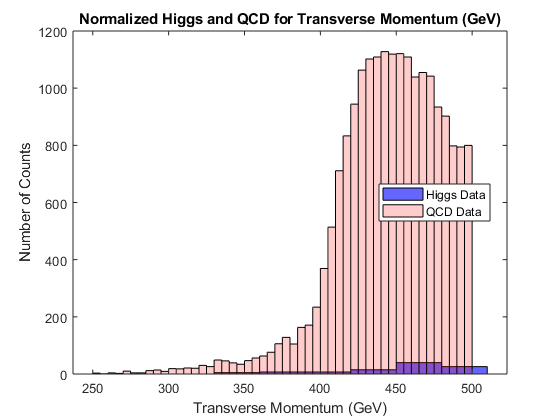

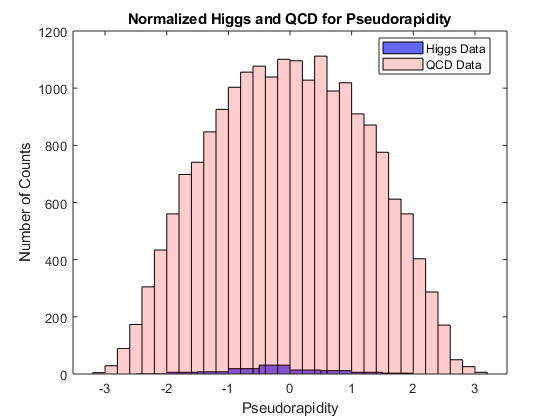

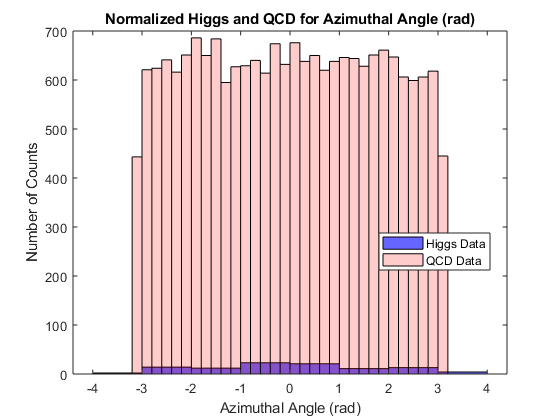

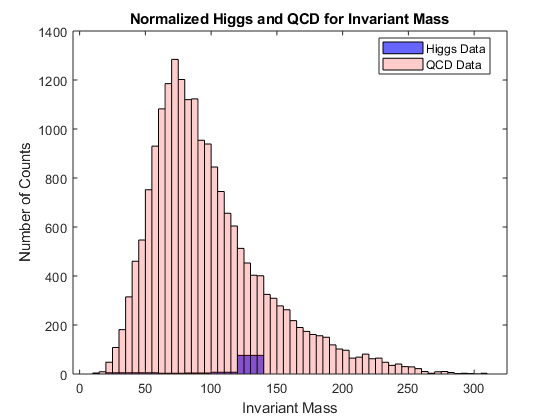

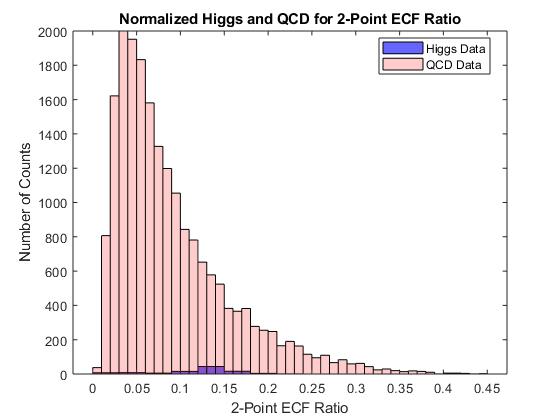

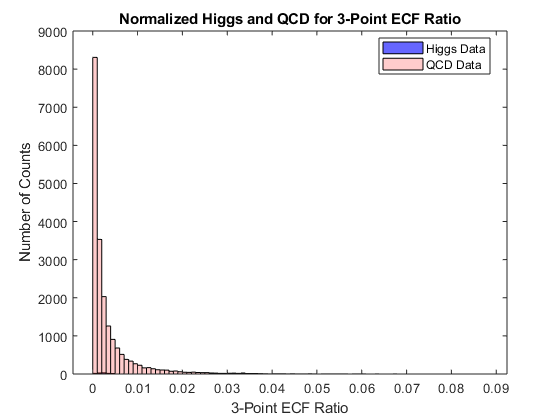

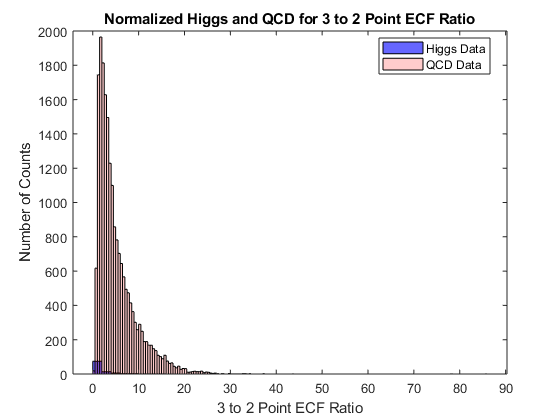

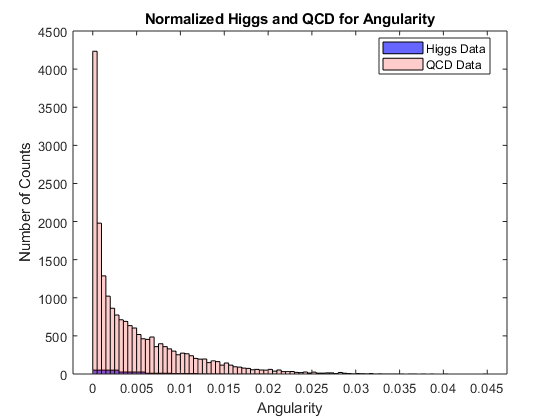

for i = 1:14
    
    figure(i+1)
    histogram(higgs_test(i,:),'FaceColor','blue'); 
    hold on 
    histogram(qcd_test(i,:),'FaceColor','red','FaceAlpha',0.2); 
    xlabel(VariableNames(i)); 
    ylabel('Number of Counts'); 
    title("Normalized Higgs and QCD for " + VariableNames(i)); 
    legend('Higgs Data','QCD Data','Location','best');     
    
end 

**Since the expected yield for the QCD background is 200 times the size of the Higgs signal, the stacked histograms above show the background data completely overshadowing the signal. This means that our ratio of N_Higgs/sqrt(N_QCD) will always be significantly less than 1. As we make different cuts to the data, this ratio will increase towards an optimum value (for each variable), though it will still remain less than 1 due to the comparative sizes of the expected yields. **

**Now, we can begin making cuts to the data. The goal of this is to omit as much QCD background while preserving as much Higgs signal as possible. As a result, our ideal discriminator variables would be ones where the Higgs histogram is neatly clustered (not spread out) in a small range compared to the spread of the QCD. This would allow us to make cuts that would remove large amounts of background data while minimizing the signal removed. We seek to find the optimal set of cuts for *****each *****variable that maximizes this signal to noise ratio. **

% creating data set for each variable 

rowNames = {'pt';'eta';'phi';'mass';'ee2';'ee3';'d2';'angularity';'t1';'t2';'t3';'t21';'t32';'KtDeltaR'}; 

**In the following section, we produce sets of cuts for each variable. In each case, we define a lower and upper threshold. All Higgs and QCD data points that fall within this range - i.e above the lower threshold and below the upper threshold - are preserved while all data points outside this range are omitted. We then calculate the signal to noise ratio, interpreted as **$\frac{N_{\mathrm{Higgs}} }{\sqrt{N_{\mathrm{QCD}} }}$**, from the size of the final preserved Higgs and QCD datasets. Since we are looking for an optimal signal to noise ratio depending on the location of our cuts (or thresholds), we iterate over a large set of possible ranges. Specfically, we split the total range of the dataset into a linearly spaced coordinate vector of 50 values. We then define a pair of lower and upper thresholds from this dataset that can be any combination of the vector values, provided that the upper threshold is greater than the lower threshold. Analyzing every combination of thresholds that satisfies this criteria yields 1250 (2500 / 2) possible ranges for each variable that we can simulate the signal to noise ratio for. Following each cut, both remaining datasets are then re-normalized by the expected yields. Afterwards, the optimal signal to noise ratio for each set and its corresponding threshold range are recorded. **

**Below are the 14 2-D surface plots displaying the SNR of each variable, for all possible combinations of ranges. The triangular nature of these plots is due to the earlier constraint that we established, which required that the upper threshold value be greater than the lower. In each plot, a red dot has been placed at the grid location corresponding to the maximum SNR ratio. For example, a dot at the location (x,y) = (upper threshold, lower threshold) means that the optimal signal to noise ratio is found by looking only at the data below x (upper threshold) and above y (lower threshold), and cutting anything outside this range.**

**In some cases on the outer edges of each variable's distribution (see the histograms), the total number of Higgs and QCD data points sharply drops off. As a result, the SNR in these ranges can be significantly high (a preserved Higgs set of 20 datapoints and a preserved QCD set of 100 could theoretically produce an SNR of 2, despite this having omitted nearly all the data from both sets). To maintain a significant degree of resolution, I added an additional constraint that required the total number of preserved data points to exceed 5000. This prevented my code from narrowing in on ideal ranges at the far end of the distributions. I have yet to explore how changing the value of this filter impacts the precision of the final ranges. Decreasing this value would allow more precise but unpopulated ranges as discussed above, while increasing this value too much would force the ideal ranges to become wide and imprecise. Ideally, there should be some optimum minimum requirement for the final dataset size that balances both sides of this spectrum. **

**A table for convenience has also been displayed below. It contains the optimum signal to noise ratio as well as its corresponding range (lower and upper thresholds) for all 14 variables. **

ratio_variableNames = {'Tested_Variable','Optimum_SNR','Lower_Threshold','Upper_Threshold'}; 
ratio_variableTypes = {'string','double','double','double'}; 
optimum_ratio = table('Size',[14 4],'VariableTypes',ratio_variableTypes,'VariableNames',ratio_variableNames); 
all_ratios = zeros(50,50,14); 

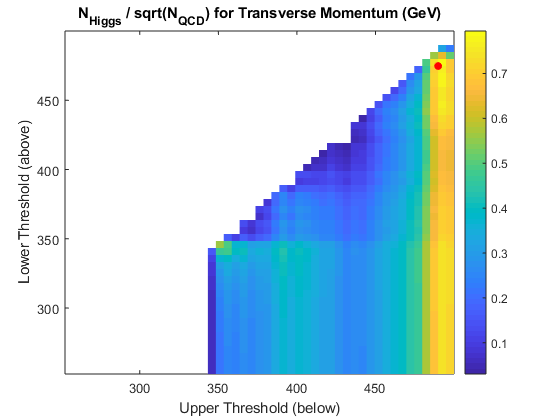

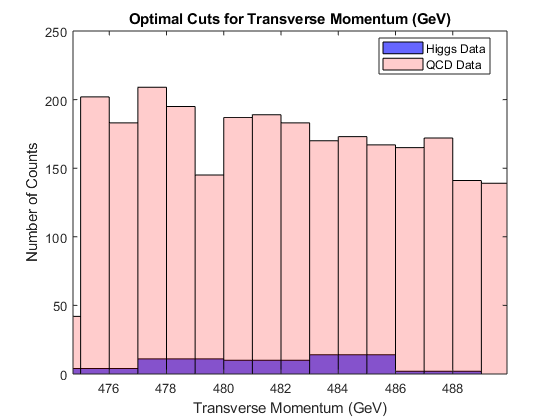

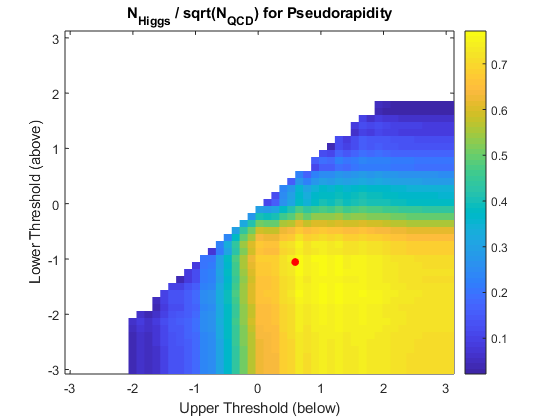

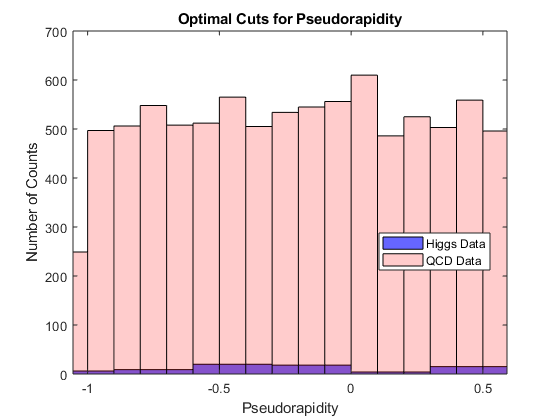

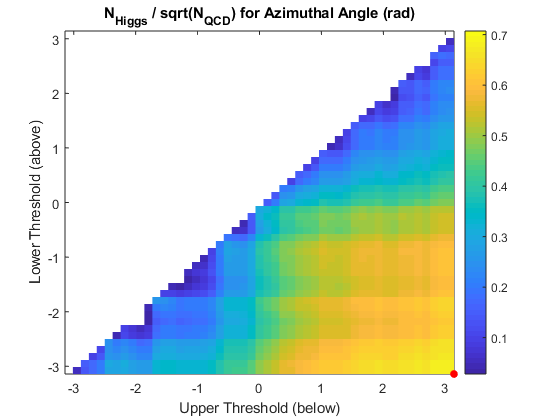

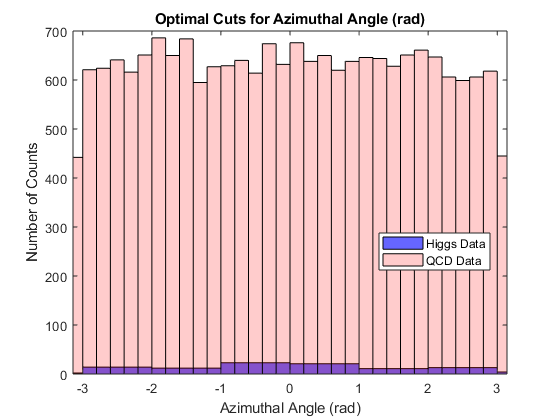

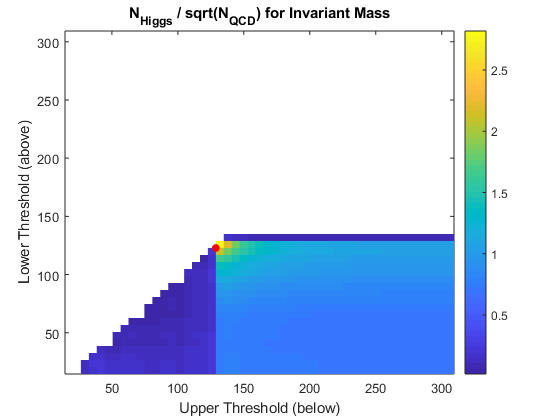

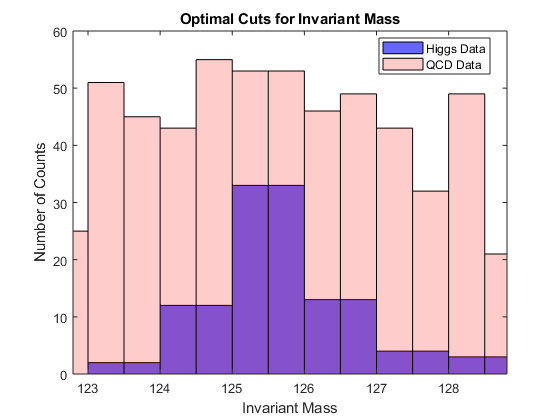

for k = 1:14
    
mins = [min(higgs_test(k,:)) min(qcd_test(k,:))]; 
maxs = [max(higgs_test(k,:)) max(qcd_test(k,:))]; 
 
steps = linspace(min(mins),max(maxs),50); 

higgs_cut = higgs_test(k,:); 
qcd_cut = qcd_test(k,:); 

[bounds,scratch] = meshgrid(steps,steps); 

for i = 1:length(steps)
    
    for j = 1:length(steps)
        
        if steps(j) <= steps(i)
            all_ratios(i,j,k) = NaN; 
            continue
        end
        
        higgs_pass = higgs_cut(higgs_cut > steps(i) & higgs_cut <= steps(j)); 
        qcd_pass = qcd_cut(qcd_cut > steps(i) & qcd_cut <= steps(j)); 
        
        if length(higgs_pass) + length(qcd_pass) < 5000
            
            all_ratios(i,j,k) = NaN; 
            
        end
        
        if isempty(qcd_pass) == 1
            
            all_ratios(i,j,k) = NaN; 
            
        else
            
            all_ratios(i,j,k) = ((numel(higgs_pass)/numel(higgs_cut))*100)/sqrt((numel(qcd_pass)/numel(qcd_cut))*20000);      
            
        end
    end
end

current_ratio = all_ratios(:,:,k); 
current_ratio(current_ratio==0) = NaN; 
all_ratios(:,:,k) = current_ratio; 

[max_ratio,index] = max(current_ratio(:)); 
[bestrow,bestcol] = ind2sub(size(current_ratio),index); 

figure(15+k)
% subplot(1,2,1)
h = pcolor(steps,steps,all_ratios(:,:,k));  
hold on 
plot(steps(bestcol),steps(bestrow),'.r','markersize',20); 
colorbar
h.EdgeColor = 'none'; 
xlabel('Upper Threshold (below)'); 
ylabel('Lower Threshold (above)'); 
title("{N_{Higgs} / sqrt(N_{QCD})} for " + VariableNames(k)); 

% subplot(1,2,2)
figure(29+k)
% histogram(higgs_cut,'FaceColor','blue');  
histogram(higgs_cut(higgs_cut > steps(bestrow) & higgs_cut <= steps(bestcol)),'FaceColor','blue'); 
hold on 
% histogram(qcd_cut,'FaceColor','red','FaceAlpha',0.2); 
histogram(qcd_cut(qcd_cut > steps(bestrow) & qcd_cut <= steps(bestcol)),'FaceColor','red','FaceAlpha',0.2); 
xlim([steps(bestrow) steps(bestcol)]);
xlabel(VariableNames(k)); 
ylabel('Number of Counts'); 
title("Optimal Cuts for " + VariableNames(k));  
legend('Higgs Data','QCD Data','location','best');  

optimum_ratio{k,1} = VariableNames(k); 
optimum_ratio{k,2} = max_ratio;
optimum_ratio{k,3} = steps(bestrow); 
optimum_ratio{k,4} = steps(bestcol); 

end


unordered_optimum_ratio = optimum_ratio; 
optimum_ratio = sortrows(optimum_ratio,2,'descend')  

optimum_ratio = 14×4 table
          Tested_Variable          Optimum_SNR    Lower_Threshold    Upper_Threshold
    ___________________________    ___________    _______________    _______________

    "Invariant Mass"                  2.8187            122.79             128.81   
    "t2"                              1.6573          0.092217            0.19419   
    "t3"                              1.6279          0.027986            0.19772   
    "t21"                             1.4965          0.054264             0.3027   
    "KtDeltaR"                        1.1465           0.45051            0.79482   
    "2-Point ECF Ratio"               1.1443           0.12196            0.17558   
    "3 to 2 Point ECF Ratio"          1.0661           0.37174             2.1188   
    "3-Point ECF Ratio"              0.90637         0.0017903         

**We now want to identify the best discriminating variables out of this data. Our original signifiance of the uncut distributions **$\frac{N_{\mathrm{Higgs}} }{\sqrt{N_{\mathrm{QCD}} }}$ **with **$N_{\mathrm{Higgs}}$ **= 100 and **$N_{\mathrm{QCD}}$ **= 20,000 was 0.7071. We can now compare the new significances of the post-cut distributions to this and see which variables, after their cuts, increased the significance the most. These would then be our ideal discriminators. The table below displays the ratio of the optimum SNR to the original SNR for all variables. **

base = 100 / sqrt(20000); 

discriminators = table('size',[14 2],'VariableNames',{'Tested_Variable','SNR_Increase'},'VariableTypes',{'string','double'}); 
discriminators{:,1} = optimum_ratio{:,1}; 
discriminators{:,2} = optimum_ratio{:,2} / base; 

% discriminators = sortrows(discriminators,2,'descend'); 
disp(discriminators)

          Tested_Variable          SNR_Increase
    ___________________________    ____________

    "Invariant Mass"                  3.9863   
    "t2"                              2.3438   
    "t3"                              2.3022   
    "t21"                             2.1164   
    "KtDeltaR"                        1.6215   
    "2-Point ECF Ratio"               1.6183   
    "3 to 2 Point ECF Ratio"          1.5077   
    "3-Point ECF Ratio"               1.2818   
    "Transverse Momentum (GeV)"       1.1238   
    "Pseudorapidity"                  1.0914   
    "Angularity"                      1.0889   
    "t32"                             1.0102   
    "t1"                               1.001   
    "Azimuthal Angle (rad)"                1   



**Looking at this table, it looks like apart from the invariant mass, that t3, t2, t21, and the 3-2 point ECF ratio are the variables with the strongest discriminating power. Now, we are curious to see if cutting the distribution data in multiple places for different variables can yield a significance higher than it would for any single set of cuts. In the following section, we look at all possible combinations of cuts for only the first 7 variables in the table above, Invariant Mass through ktDeltaR, which had significances of over 1. By all possible combinations of cuts, I mean that from the first 7 variables, any number of thresholds may be applied. So if [A B C D E F G] describes the thresholds for the first 7 features, then the combination of cuts [A B] is just as viable as the combination [A C D] or [A C D E F]. Essentially, we will be finding the significance of *****all *****ordered subsets of the cuts. **

**For a jet to pass the multiple applied thresholds, the value for each of its variables must fall within the thresholds describing the cuts for each variable. I ran this code a few different ways and settled on the methodology below. Our earlier criteria for making the cuts was highly sensitive to the Higgs data - because the expected yields were 100 vs. 20,000, any cut that removed a single Higgs data point would only improve the significance if the same cut removed more than 200 QCD points. As a result, the thresholds we found earlier were able to preserve the vast majority of the signal data. But since these same cuts removed vast parts of the background data, I began to run into the same problem earlier where I could be getting extremely high significance values due to the fact that only a few total data points were being preserved. This effect was even more pronounced when combining multiple thresholds as below (a series of 5 cuts could potentially yield a significance of 10 while only looking at 20 points total). Therefore, I applied a similar filter as the one earlier, and required each combination of cuts to have *****at least *****a certain number of data points in order for the significance to be considered viable. **

%manually reordering higgs and qcd datasets to match sorted order of tables

hrow1 = higgs_test(4,:); qrow1 = qcd_test(4,:); 
hrow2 = higgs_test(11,:); qrow2 = qcd_test(11,:); 
hrow3 = higgs_test(10,:); qrow3 = qcd_test(10,:); 
hrow4 = higgs_test(12,:); qrow4 = qcd_test(12,:); 
hrow5 = higgs_test(7,:); qrow5 = qcd_test(7,:); 
hrow6 = higgs_test(5,:); qrow6 = qcd_test(5,:); 
hrow7 = higgs_test(14,:); qrow7 = qcd_test(14,:); 

higgs_ordered = [hrow1; hrow2; hrow3; hrow4; hrow5; hrow6; hrow7]; 
qcd_ordered = [qrow1; qrow2; qrow3; qrow4; qrow5; qrow6; qrow7]; 
 
%creating ordered subsets of first 7 variables
set1 = nchoosek(1:7,1); set1sig = zeros(length(set1),1);  
set2 = nchoosek(1:7,2); set2sig = zeros(length(set2),1); 
set3 = nchoosek(1:7,3); set3sig = zeros(length(set3),1); 
set4 = nchoosek(1:7,4); set4sig = zeros(length(set4),1); 
set5 = nchoosek(1:7,5); set5sig = zeros(length(set5),1); 
set6 = nchoosek(1:7,6); set6sig = zeros(length(set6),1); 
set7 = nchoosek(1:7,7); set7sig = zeros(length(set7),1); 

hpasslist1 = zeros(1,length(set1)); 
qpasslist1 = zeros(1,length(set1)); 

for i = 1:length(set1)
    
    ind = set1(i); 
    hpass = numel(higgs_ordered(higgs_ordered(i,:) > optimum_ratio{i,3} & higgs_ordered(i,:) <= optimum_ratio{i,4})); 
    num = hpass; 
    qpass = numel(qcd_ordered(qcd_ordered(i,:) > optimum_ratio{i,3} & qcd_ordered(i,:) <= optimum_ratio{i,4})); 
    den = sqrt(qpass);
    set1sig(i) = num/den;     
    hpasslist1(i) = hpass; 
    qpasslist1(i) = qpass; 
    
end

hpasslist2 = zeros(1,length(set2)); 
qpasslist2 = zeros(1,length(set2)); 

for i = 1:length(set2)
    
    ind = set2(i,:); 
    hpass = numel(higgs_ordered(higgs_ordered(ind(1),:) > optimum_ratio{ind(1),3} & higgs_ordered(ind(1),:) <= optimum_ratio{ind(1),4} & ...
        higgs_ordered(ind(2),:) > optimum_ratio{ind(2),3} & higgs_ordered(ind(2),:) <= optimum_ratio{ind(2),4})); 
    qpass = numel(qcd_ordered(qcd_ordered(ind(1),:) > optimum_ratio{ind(1),3} & qcd_ordered(ind(1),:) <= optimum_ratio{ind(1),4} & ...
        qcd_ordered(ind(2),:) > optimum_ratio{ind(2),3} & qcd_ordered(ind(2),:) <= optimum_ratio{ind(2),4})); 
    set2sig(i) = hpass*100/sqrt(qpass*20000);  
    hpasslist2(i) = hpass; 
    qpasslist2(i) = qpass; 
    if hpasslist2(i) + qpasslist2(i) < 200
        set2sig(i) = NaN; 
    end
    
end

hpasslist3 = zeros(1,length(set3)); 
qpasslist3 = zeros(1,length(set3)); 

for i = 1:length(set3)
    
    ind = set3(i,:); 
    hpass = numel(higgs_ordered(higgs_ordered(ind(1),:) > optimum_ratio{ind(1),3} & higgs_ordered(ind(1),:) <= optimum_ratio{ind(1),4} & ...
        higgs_ordered(ind(2),:) > optimum_ratio{ind(2),3} & higgs_ordered(ind(2),:) <= optimum_ratio{ind(2),4} & ...
        higgs_ordered(ind(3),:) > optimum_ratio{ind(3),3} & higgs_ordered(ind(3),:) <= optimum_ratio{ind(3),4})); 
    qpass = numel(qcd_ordered(qcd_ordered(ind(1),:) > optimum_ratio{ind(1),3} & qcd_ordered(ind(1),:) <= optimum_ratio{ind(1),4} & ...
        qcd_ordered(ind(2),:) > optimum_ratio{ind(2),3} & qcd_ordered(ind(2),:) <= optimum_ratio{ind(2),4} & ...
        qcd_ordered(ind(3),:) > optimum_ratio{ind(3),3} & qcd_ordered(ind(3),:) <= optimum_ratio{ind(3),4})); 
    set3sig(i) = hpass*100/sqrt(qpass*20000); 
    hpasslist3(i) = hpass; 
    qpasslist3(i) = qpass; 
    if hpasslist3(i) + qpasslist3(i) < 150
        set3sig(i) = NaN; 
    end
    
end

hpasslist4 = zeros(1,length(set4)); 
qpasslist4 = zeros(1,length(set4)); 

for i = 1:length(set4)
    
    ind = set4(i,:); 
    hpass = numel(higgs_ordered(higgs_ordered(ind(1),:) > optimum_ratio{ind(1),3} & higgs_ordered(ind(1),:) <= optimum_ratio{ind(1),4} & ...
        higgs_ordered(ind(2),:) > optimum_ratio{ind(2),3} & higgs_ordered(ind(2),:) <= optimum_ratio{ind(2),4} & ...
        higgs_ordered(ind(3),:) > optimum_ratio{ind(3),3} & higgs_ordered(ind(3),:) <= optimum_ratio{ind(3),4} & ...
        higgs_ordered(ind(4),:) > optimum_ratio{ind(4),3} & higgs_ordered(ind(4),:) <= optimum_ratio{ind(4),4})); 
    qpass = numel(qcd_ordered(qcd_ordered(ind(1),:) > optimum_ratio{ind(1),3} & qcd_ordered(ind(1),:) <= optimum_ratio{ind(1),4} & ...
        qcd_ordered(ind(2),:) > optimum_ratio{ind(2),3} & qcd_ordered(ind(2),:) <= optimum_ratio{ind(2),4} & ...
        qcd_ordered(ind(3),:) > optimum_ratio{ind(3),3} & qcd_ordered(ind(3),:) <= optimum_ratio{ind(3),4} & ...
        qcd_ordered(ind(4),:) > optimum_ratio{ind(4),3} & qcd_ordered(ind(4),:) <= optimum_ratio{ind(4),4})); 
    set4sig(i) = hpass*100/sqrt(20000*qpass); 
    hpasslist4(i) = hpass; 
    qpasslist4(i) = qpass; 
    if hpasslist4(i) + qpasslist4(i) < 100
        set4sig(i) = NaN; 
    end
    
end

hpasslist5 = zeros(1,length(set5)); 
qpasslist5 = zeros(1,length(set5)); 

for i = 1:length(set5)
    
    ind = set5(i,:); 
    hpass = numel(higgs_ordered(higgs_ordered(ind(1),:) > optimum_ratio{ind(1),3} & higgs_ordered(ind(1),:) <= optimum_ratio{ind(1),4} & ...
        higgs_ordered(ind(2),:) > optimum_ratio{ind(2),3} & higgs_ordered(ind(2),:) <= optimum_ratio{ind(2),4} & ...
        higgs_ordered(ind(3),:) > optimum_ratio{ind(3),3} & higgs_ordered(ind(3),:) <= optimum_ratio{ind(3),4} & ...
        higgs_ordered(ind(4),:) > optimum_ratio{ind(4),3} & higgs_ordered(ind(4),:) <= optimum_ratio{ind(4),4} & ...
        higgs_ordered(ind(5),:) > optimum_ratio{ind(5),3} & higgs_ordered(ind(5),:) <= optimum_ratio{ind(5),4})); 
    qpass = numel(qcd_ordered(qcd_ordered(ind(1),:) > optimum_ratio{ind(1),3} & qcd_ordered(ind(1),:) <= optimum_ratio{ind(1),4} & ...
        qcd_ordered(ind(2),:) > optimum_ratio{ind(2),3} & qcd_ordered(ind(2),:) <= optimum_ratio{ind(2),4} & ...
        qcd_ordered(ind(3),:) > optimum_ratio{ind(3),3} & qcd_ordered(ind(3),:) <= optimum_ratio{ind(3),4} & ...
        qcd_ordered(ind(4),:) > optimum_ratio{ind(4),3} & qcd_ordered(ind(4),:) <= optimum_ratio{ind(4),4} & ...
        qcd_ordered(ind(5),:) > optimum_ratio{ind(5),3} & qcd_ordered(ind(5),:) <= optimum_ratio{ind(5),4})); 
    set5sig(i) = hpass*100/sqrt(qpass*20000); 
    hpasslist5(i) = hpass; 
    qpasslist5(i) = qpass; 
    if hpasslist5(i) + qpasslist5(i) < 75
        set5sig(i) = NaN; 
    end
    
end

hpasslist6 = zeros(1,length(set6)); 
qpasslist6 = zeros(1,length(set6)); 

for i = 1:length(set6)
    
    ind = set6(i,:); 
    hpass = numel(higgs_ordered(higgs_ordered(ind(1),:) > optimum_ratio{ind(1),3} & higgs_ordered(ind(1),:) <= optimum_ratio{ind(1),4} & ...
        higgs_ordered(ind(2),:) > optimum_ratio{ind(2),3} & higgs_ordered(ind(2),:) <= optimum_ratio{ind(2),4} & ...
        higgs_ordered(ind(3),:) > optimum_ratio{ind(3),3} & higgs_ordered(ind(3),:) <= optimum_ratio{ind(3),4} & ...
        higgs_ordered(ind(4),:) > optimum_ratio{ind(4),3} & higgs_ordered(ind(4),:) <= optimum_ratio{ind(4),4} & ...
        higgs_ordered(ind(5),:) > optimum_ratio{ind(5),3} & higgs_ordered(ind(5),:) <= optimum_ratio{ind(5),4} & ...
        higgs_ordered(ind(6),:) > optimum_ratio{ind(6),3} & higgs_ordered(ind(6),:) <= optimum_ratio{ind(6),4})); 
    qpass = numel(qcd_ordered(qcd_ordered(ind(1),:) > optimum_ratio{ind(1),3} & qcd_ordered(ind(1),:) <= optimum_ratio{ind(1),4} & ...
        qcd_ordered(ind(2),:) > optimum_ratio{ind(2),3} & qcd_ordered(ind(2),:) <= optimum_ratio{ind(2),4} & ...
        qcd_ordered(ind(3),:) > optimum_ratio{ind(3),3} & qcd_ordered(ind(3),:) <= optimum_ratio{ind(3),4} & ...
        qcd_ordered(ind(4),:) > optimum_ratio{ind(4),3} & qcd_ordered(ind(4),:) <= optimum_ratio{ind(4),4} & ...
        qcd_ordered(ind(5),:) > optimum_ratio{ind(5),3} & qcd_ordered(ind(5),:) <= optimum_ratio{ind(5),4} & ...
        qcd_ordered(ind(6),:) > optimum_ratio{ind(6),3} & qcd_ordered(ind(6),:) <= optimum_ratio{ind(6),4})); 
    set6sig(i) = hpass*100/sqrt(qpass*20000); 
    hpasslist6(i) = hpass; 
    qpasslist6(i) = qpass; 
    if hpasslist6(i) + qpasslist6(i) < 50
        set6sig(i) = NaN; 
    end
    
end

hpasslist7 = zeros(1,length(set7)); 
qpasslist7 = zeros(1,length(set7)); 

for i = 1:length(set7)
    
    ind = set7(1,:); 
    hpass = numel(higgs_ordered(higgs_ordered(ind(1),:) > optimum_ratio{ind(1),3} & higgs_ordered(ind(1),:) <= optimum_ratio{ind(1),4} & ...
        higgs_ordered(ind(2),:) > optimum_ratio{ind(2),3} & higgs_ordered(ind(2),:) <= optimum_ratio{ind(2),4} & ...
        higgs_ordered(ind(3),:) > optimum_ratio{ind(3),3} & higgs_ordered(ind(3),:) <= optimum_ratio{ind(3),4} & ...
        higgs_ordered(ind(4),:) > optimum_ratio{ind(4),3} & higgs_ordered(ind(4),:) <= optimum_ratio{ind(4),4} & ...
        higgs_ordered(ind(5),:) > optimum_ratio{ind(5),3} & higgs_ordered(ind(5),:) <= optimum_ratio{ind(5),4} & ...
        higgs_ordered(ind(6),:) > optimum_ratio{ind(6),3} & higgs_ordered(ind(6),:) <= optimum_ratio{ind(6),4} & ...
        higgs_ordered(ind(7),:) > optimum_ratio{ind(7),3} & higgs_ordered(ind(7),:) <= optimum_ratio{ind(7),4})); 
    qpass = numel(qcd_ordered(qcd_ordered(ind(1),:) > optimum_ratio{ind(1),3} & qcd_ordered(ind(1),:) <= optimum_ratio{ind(1),4} & ...
        qcd_ordered(ind(2),:) > optimum_ratio{ind(2),3} & qcd_ordered(ind(2),:) <= optimum_ratio{ind(2),4} & ...
        qcd_ordered(ind(3),:) > optimum_ratio{ind(3),3} & qcd_ordered(ind(3),:) <= optimum_ratio{ind(3),4} & ...
        qcd_ordered(ind(4),:) > optimum_ratio{ind(4),3} & qcd_ordered(ind(4),:) <= optimum_ratio{ind(4),4} & ...
        qcd_ordered(ind(5),:) > optimum_ratio{ind(5),3} & qcd_ordered(ind(5),:) <= optimum_ratio{ind(5),4} & ...
        qcd_ordered(ind(6),:) > optimum_ratio{ind(6),3} & qcd_ordered(ind(6),:) <= optimum_ratio{ind(6),4} & ...
        qcd_ordered(ind(7),:) > optimum_ratio{ind(7),3} & qcd_ordered(ind(7),:) <= optimum_ratio{ind(7),4})); 
    set7sig(i) = hpass*100/sqrt(qpass*20000); 
    hpasslist7(i) = hpass; 
    qpasslist7(i) = qpass; 
    if hpasslist7(i) + qpasslist7(i) < 20 
        set7sig(i) = NaN; 
    end
    
end

**Below are 7 scatter plots showing the resulting significances from these calculations. The first scatter plot has only a single set of cuts; the second plot features two sets of cuts, and so on. **

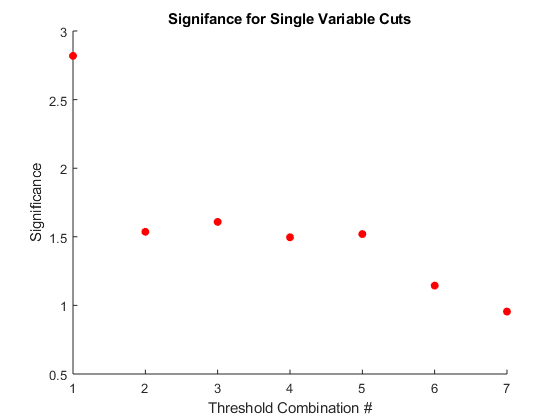

figure(45) 
scatter(1:length(set1sig),set1sig,'red','filled'); 
xticks(1:1:length(set1sig)); 
xlabel('Threshold Combination #'); 
ylabel('Significance'); 
title('Signifance for Single Variable Cuts'); 

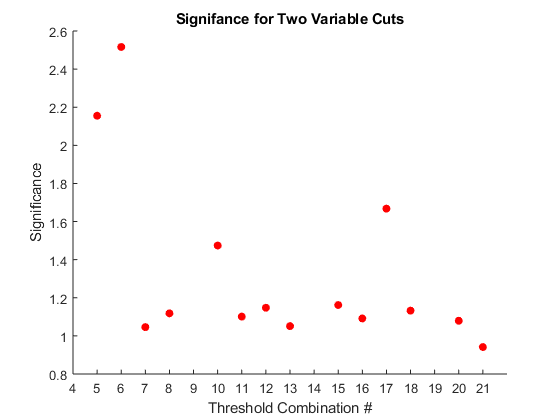


figure(46) 
scatter(1:length(set2sig),set2sig,'red','filled'); 
xticks(1:1:length(set2sig)); 
xlabel('Threshold Combination #'); 
ylabel('Significance'); 
title('Signifance for Two Variable Cuts'); 

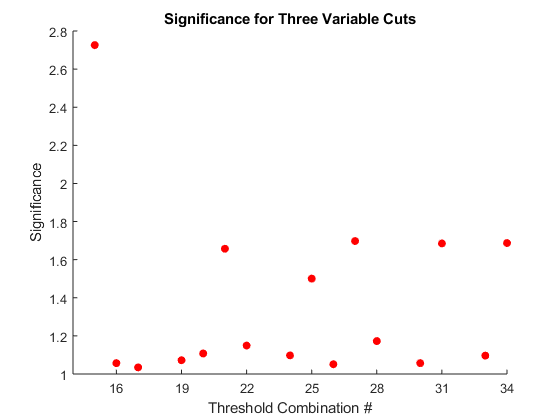


figure(47) 
scatter(1:length(set3sig),set3sig,'red','filled'); 
xticks(1:3:length(set3sig)); 
xlabel('Threshold Combination #'); 
ylabel('Significance'); 
title('Significance for Three Variable Cuts'); 

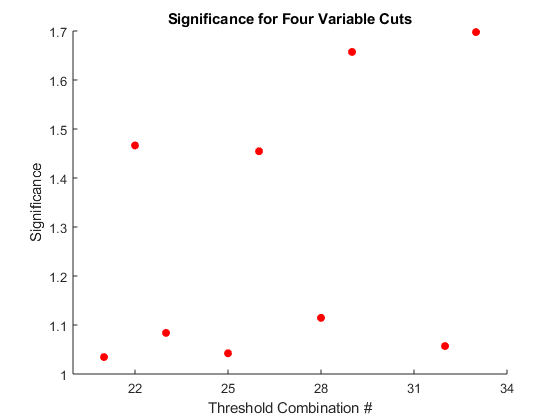


figure(48) 
scatter(1:length(set4sig),set4sig,'red','filled'); 
xticks(1:3:length(set4sig)); 
xlabel('Threshold Combination #'); 
ylabel('Significance'); 
title('Significance for Four Variable Cuts'); 

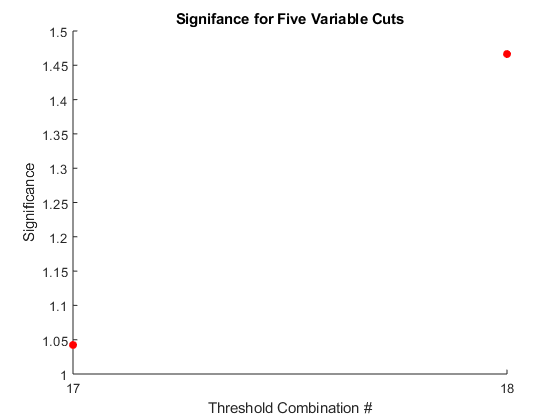


figure(49) 
scatter(1:length(set5sig),set5sig,'red','filled'); 
xticks(1:1:length(set5sig)); 
xlabel('Threshold Combination #'); 
ylabel('Significance'); 
title('Signifance for Five Variable Cuts'); 

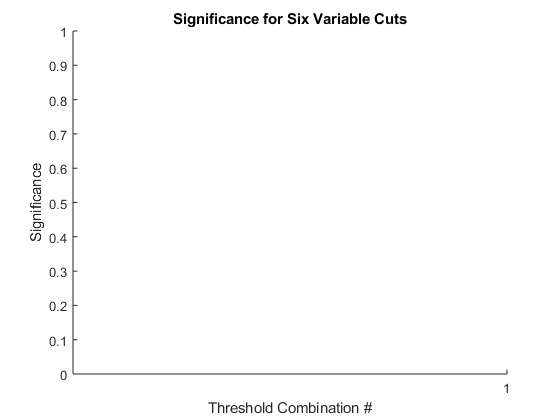


figure(50)
scatter(1:length(set6sig),set6sig,'red','filled'); 
xticks(1:1:length(set6sig)); 
xlabel('Threshold Combination #'); 
ylabel('Significance'); 
title('Significance for Six Variable Cuts'); 

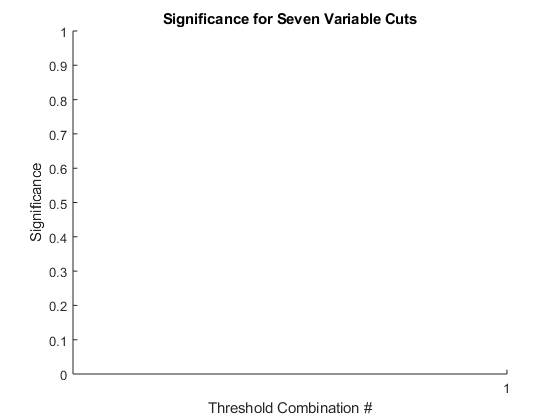


figure(51)
scatter(1:length(set7sig),set7sig,'red','filled'); 
xticks(1:1:length(set7sig)); 
xlabel('Threshold Combination #'); 
ylabel('Significance'); 
title('Significance for Seven Variable Cuts'); 

**A quick point of order - every time I run this code, these plots look different, and give varying values for the signifcances. I have no clue why, as none of my variables or values are changing. I have checked this multiple times, and cannot seem to find the issue. For the following discussion, I picked values from the most stable iterations of the code, i.e instances in which the significance from run to run did not change much. As a result, the values stated in the next paragraph might be different than what the plots show, but they are correct nonetheless. I have more confidence in the values I state shortly than what the plots show, so for any discrepancy between the two, please consider only what is discussed below, as those are my final results. **

**Inspecting the graphs above (and manually omitting some datapoints , it looks like we can push our final significance up to about 2.5 by using an optimum selection of three cuts, but only up to 2.3 using four cuts. I have less confidence in the 2.3 result from using 4 cuts, as I think that in this case our total dataset size is growing questionably small. Similarly, the minimum dataset size requirement that I imposed did not seem to have much impact when trying to apply six or seven cuts, as those significances remained high in the range of 4 sigma and above, or had two few data points to be computed trustfully. Though there is nothing inherently wrong with this significance result, I feel that after applying this many cuts, the data just became too granular and its size too small for our significance calculation to be correct. Below, I have listed the maximum significance and its associated cuts for the three and four variable cut data. The middle column of the table corresponds to the lower threshold for the cut (omitting all values below this), and the last column of the table corresponds to the upper threshold (omitting all values above this). The plots for five, six, and seven cuts are either very sparse or empty altogether since the criteria for minimum number of total data points was not met. **

[d1, ix1] = max(set3sig); 
[d2, ix2] = max(set4sig); 

disp("For a set of 3 cuts, the maximum significance is " + d1 + ", given by the following cuts:")

For a set of 3 cuts, the maximum significance is 2.7261, given by the following cuts:


disp(optimum_ratio{[set3(ix1,:)],[1 3 4]})

    "Invariant Mass"            "122.7928"     "128.8089" 
    "2-Point ECF Ratio"         "0.1219639"    "0.1755776"
    "3 to 2 Point ECF Ratio"    "0.3717353"    "2.118818" 




disp("For a set of 4 cuts, the maximum significance is " + d2 + ", given by the following cuts:")

For a set of 4 cuts, the maximum significance is 1.6977, given by the following cuts:


disp(optimum_ratio{[set4(ix2,:)],[1 3 4]})

    "t3"                        "0.0279861"     "0.1977191"
    "t21"                       "0.05426439"    "0.3026994"
    "2-Point ECF Ratio"         "0.1219639"     "0.1755776"
    "3 to 2 Point ECF Ratio"    "0.3717353"     "2.118818" 



**This completes the event selection optimization portion of Labs 7 and 8. To recap - we were given datasets of 100,000 jets for Higgs signal and QCD background data, with each jet containing information about 14 different variables. After normalizing each distribution by the expected yield for the signal (100) and background (20,000), the background distribution heavily overshadowed the signal data. As a result, we sought to cut out portions of the data in order to maximize the significance of finding our signal against the backgroud. We did this by defining value thresholds for each of 14 variables, and 'cut' all the data that did not fall within these bounds. After independently iterating this over the 7 variables shown to impact the significance the most, we then combined our ideal thresholds for multiple variables, in order to raise the significance even higher. This was succesful, considering that our highest significance (or SNR) obtained by cutting only a single variable was 1.74, whereas we were able to raise it to 2.4652 and a more conservative 2.3216 by cutting the data in 3 and 4 dimensions, respectively. **

**Next, we will try and hunt for a signal using these optimized event selection criteria on a pseudo-experiment dataset. **

#### **Lab 8: Pseudo-Experiment Data Analysis**

**As mentioned above, we will now try and hunt for a signal in low and high luminosity psuedo-experiment data, using the optimal event selection criteria we found in Lab 7. **

h5disp("data_highLumi_pt_250_500.h5")

HDF5 data_highLumi_pt_250_500.h5 
Group '/' 
    Attributes:
        'TITLE':  ''
        'CLASS':  'GROUP'
        'VERSION':  '1.0'
        'PYTABLES_FORMAT_VERSION':  '2.1'
    Group '/data' 
        Attributes:
            'TITLE':  ''
            'CLASS':  'GROUP'
            'VERSION':  '1.0'
            'pandas_type':  'frame'
            'pandas_version':  '0.15.2'
            'encoding':  'UTF-8'
            'errors':  'strict'
            'ndim':  2
            'axis0_variety':  'regular'
            'axis1_variety':  'regular'
            'nblocks':  1
            'block0_items_variety':  'regular'
        Dataset 'axis0' 
            Size:  14
            MaxSize:  14
            Datatype:   H5T_STRING
                String Length: 10
                Padding: H5T_STR_NULLTERM
                Character Set: H5T_CSET_ASCII
                Character Type: H5T_C_S1
            ChunkSize:  []
            Filters:  none
            FillValue:  '          '
            Attributes

h5disp("data_lowLumi_pt_250_500.h5")

HDF5 data_lowLumi_pt_250_500.h5 
Group '/' 
    Attributes:
        'TITLE':  ''
        'CLASS':  'GROUP'
        'VERSION':  '1.0'
        'PYTABLES_FORMAT_VERSION':  '2.1'
    Group '/data' 
        Attributes:
            'TITLE':  ''
            'CLASS':  'GROUP'
            'VERSION':  '1.0'
            'pandas_type':  'frame'
            'pandas_version':  '0.15.2'
            'encoding':  'UTF-8'
            'errors':  'strict'
            'ndim':  2
            'axis0_variety':  'regular'
            'axis1_variety':  'regular'
            'nblocks':  1
            'block0_items_variety':  'regular'
        Dataset 'axis0' 
            Size:  14
            MaxSize:  14
            Datatype:   H5T_STRING
                String Length: 10
                Padding: H5T_STR_NULLTERM
                Character Set: H5T_CSET_ASCII
                Character Type: H5T_C_S1
            ChunkSize:  []
            Filters:  none
            FillValue:  '          '
            Attributes:


high_id = h5read("data_highLumi_pt_250_500.h5",'/data/block0_items');
high_lum = h5read("data_highLumi_pt_250_500.h5",'/data/block0_values');
low_id = h5read("data_lowLumi_pt_250_500.h5",'/data/block0_items');
low_lum = h5read("data_lowLumi_pt_250_500.h5",'/data/block0_values');

**First, we analyze the high luminosity data. Below are the stacked histograms for all 14 variables, this time plotting the Higgs Signal, QCD Background, *****and *****the high luminosity experimental data. Each has been appropriately normalized by its expected yield - with N_Higgs = 100, N_QCD = 20,000, and N_HighLum = 20,100. **

higgs_expected_yield = randi([1 100000],1,100); 
qcd_expected_yield = randi([1 100000],1,20000); 
high_expected_yield = randi([1 length(high_lum)],1,20100); 

higgs_test = higgs{:,higgs_expected_yield}; 
qcd_test = qcd{:,qcd_expected_yield}; 
high_test = high_lum(:,high_expected_yield); 

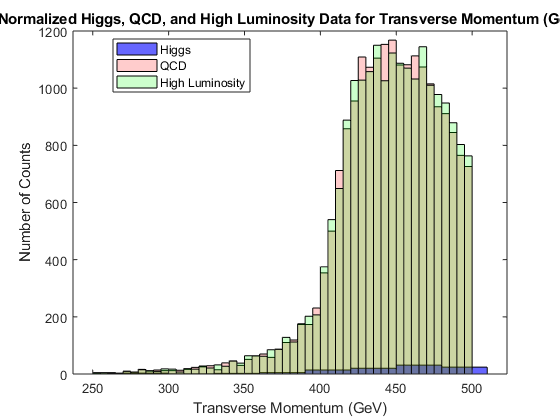

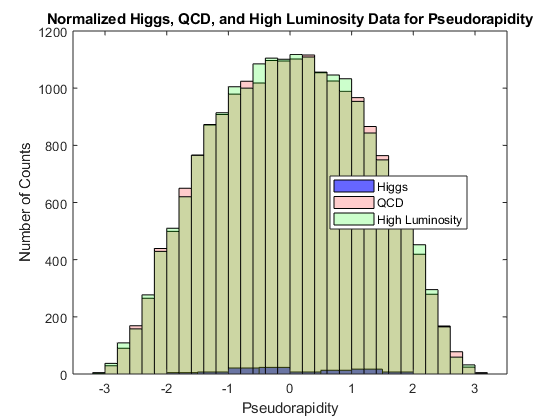

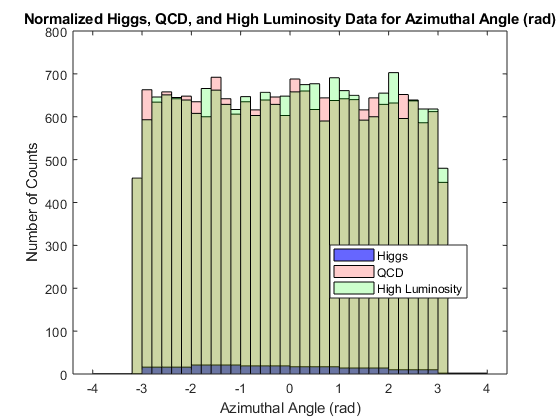

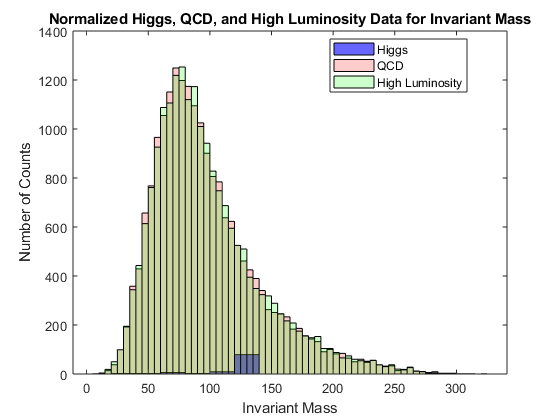

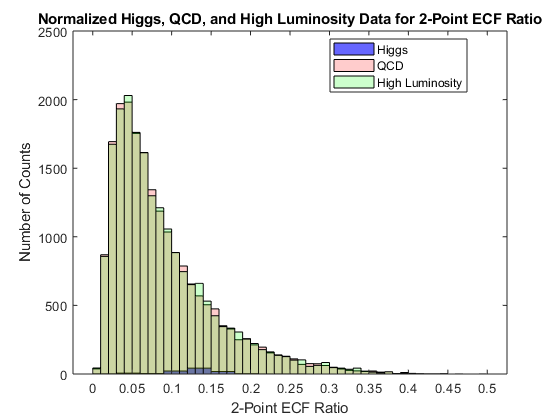

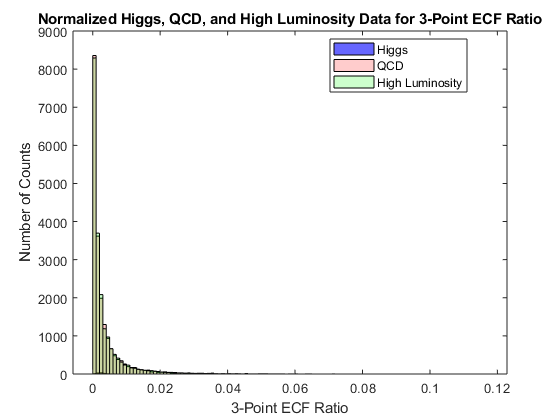

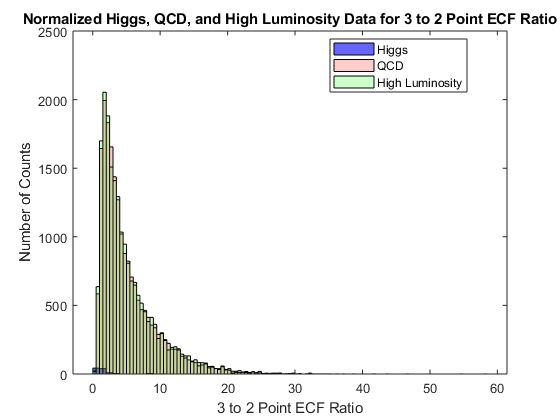

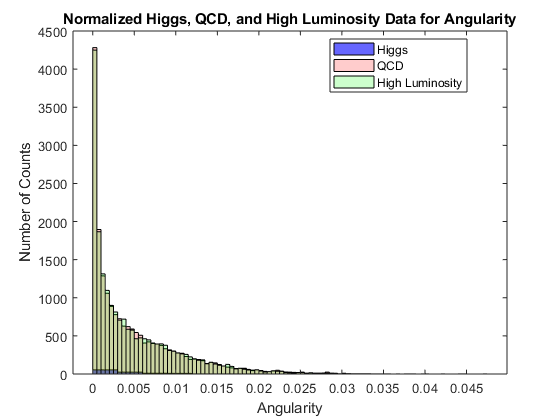

for i = 1:14
    
    figure(i+100)
    histogram(higgs_test(i,:),'FaceColor','blue'); 
    hold on 
    histogram(qcd_test(i,:),'FaceColor','red','FaceAlpha',0.2); 
    hold on 
    histogram(high_test(i,:),'FaceColor','green','FaceAlpha',0.2); 
    xlabel(VariableNames(i)); 
    ylabel('Number of Counts'); 
    title("Normalized Higgs, QCD, and High Luminosity Data for " + VariableNames(i)); 
    legend('Higgs','QCD','High Luminosity','Location','best');     
    
end 

**As we expected, the high luminosity data (being the sum of the higgs signal and qcd background) almost perfectly matches the histogram for the background distribution (since the signal is so comparatively small). We can now produce the same plots, but this time within the optimal thresholds we found earlier in the lab. This time, we should hopefully expect the high luminosity distribution to resemble the Higgs distribution a little bit better (though not very well), since much of our QCD background has been filtered out. **

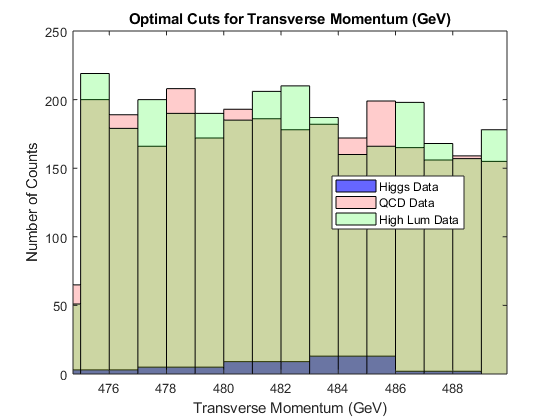

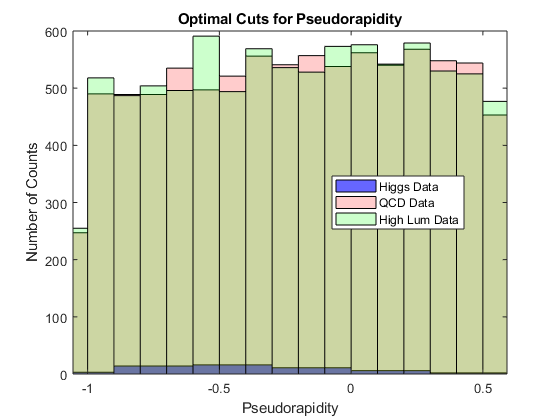

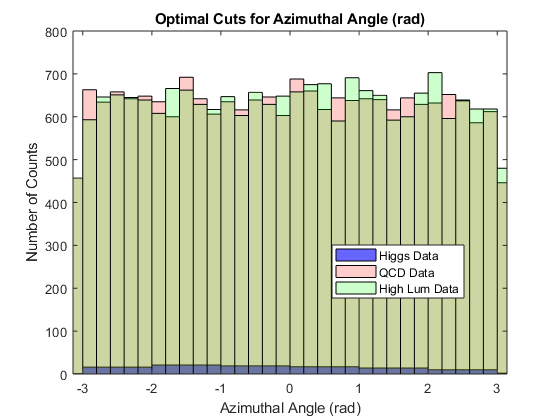

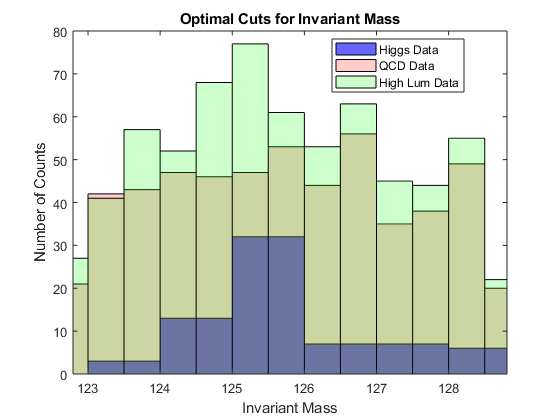

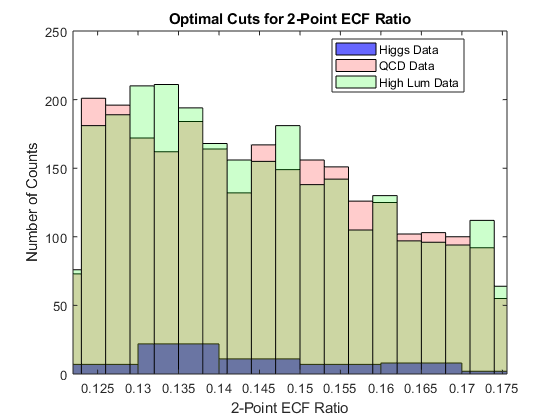

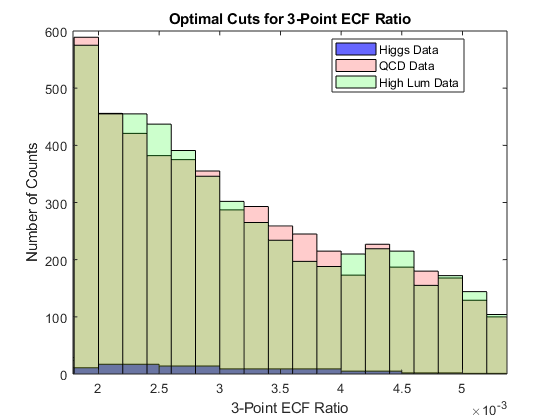

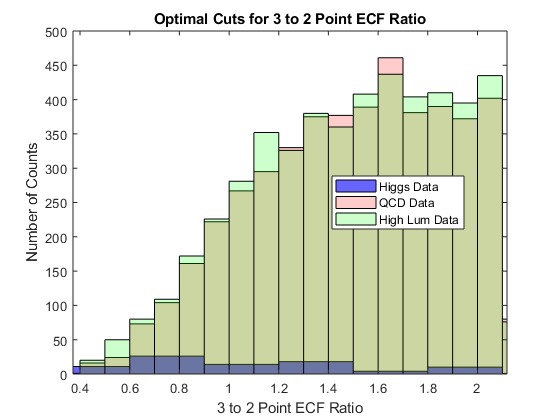

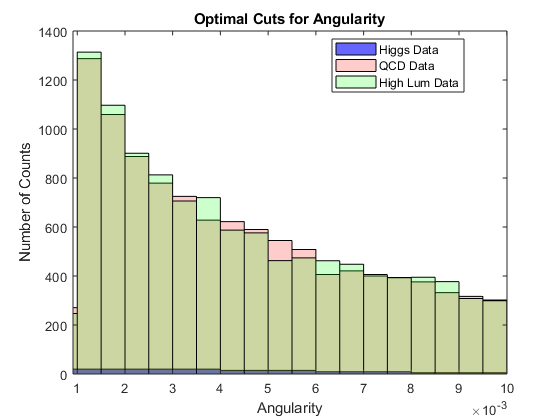

for j = 1:14
    
    higgs_cut = higgs_test(j,:); 
    qcd_cut = qcd_test(j,:); 
    high_lum_cut = high_test(j,:); 
    
    figure(114 + j)
    histogram(higgs_cut(higgs_cut > unordered_optimum_ratio{j,3} & higgs_cut <= unordered_optimum_ratio{j,4}),'FaceColor','blue')
    hold on 
    histogram(qcd_cut(qcd_cut > unordered_optimum_ratio{j,3} & qcd_cut <= unordered_optimum_ratio{j,4}),'FaceColor','red','FaceAlpha',0.2)
    hold on 
    histogram(high_lum_cut(high_lum_cut > unordered_optimum_ratio{j,3} & high_lum_cut <= unordered_optimum_ratio{j,4}),'FaceColor','green','FaceAlpha',0.2)
    
    xlim([unordered_optimum_ratio{j,3} unordered_optimum_ratio{j,4}]); 
    xlabel(VariableNames(j))
    ylabel('Number of Counts') 
    title("Optimal Cuts for " + VariableNames(j)); 
    legend('Higgs Data','QCD Data','High Lum Data','Location','best'); 
    
end

**The results were not as good as expected, as the high luminosity distribution doesn't more closely resemble the Higgs signal. Instead, it looks as if within each optimum threshold, the high luminosity histogram more accurately resembles the sum of the signal and background histograms. In fact, I think this actually makes perfect sense - since we are cutting all data that falls outside these bounds, we would expect whatever remains inside to resemble the sum of its constituents. So perhaps my earlier expectation that the high luminosity distribution closely match the Higgs signal was a little misguided. Using these same optimum thresholds, we will try and calculate the significance of the high luminosity data and compare it to the significances we obtained from the pure training data of N_Higgs and N_QCD. **

ratio_variableNames = {'Tested_Variable','Training_Set_SNR','High_Lum_SNR','Percent_Diff'}; 
ratio_variableTypes = {'string','double','double','double'}; 
unordered_high_lum_ratio = table('Size',[14 4],'VariableTypes',ratio_variableTypes,'VariableNames',ratio_variableNames); 

for k = 1:14
    
    higgs_cut = higgs_test(k,:); 
    qcd_cut = qcd_test(k,:); 
    high_lum_cut = high_test(k,:); 
    
    num_higgs = numel(higgs_cut(higgs_cut > unordered_optimum_ratio{k,3} & higgs_cut <= unordered_optimum_ratio{k,4})); 
    num_qcd = numel(qcd_cut(qcd_cut > unordered_optimum_ratio{k,3} & qcd_cut <= unordered_optimum_ratio{k,4})); 
    num_high_lum = numel(high_lum_cut(high_lum_cut > unordered_optimum_ratio{k,3} & high_lum_cut <= unordered_optimum_ratio{k,4})); 
    
    unordered_high_lum_ratio{k,1} = VariableNames(k); 
    unordered_high_lum_ratio{k,2} = unordered_optimum_ratio{k,2}; 
    unordered_high_lum_ratio{k,3} = num_higgs/sqrt(num_high_lum); 
    unordered_high_lum_ratio{k,4} = (unordered_high_lum_ratio{k,3}-unordered_high_lum_ratio{k,2})/unordered_high_lum_ratio{k,2} * 100; 
    
end

high_lum_ratio = sortrows(unordered_high_lum_ratio,2,'descend'); 
disp(high_lum_ratio)

          Tested_Variable          Training_Set_SNR    High_Lum_SNR    Percent_Diff
    ___________________________    ________________    ____________    ____________

    "Invariant Mass"                    2.8187            2.6369          -6.4492  
    "t2"                                1.6573            1.5236          -8.0687  
    "t3"                                1.6279            1.7861           9.7156  
    "t21"                               1.4965             1.456          -2.7074  
    "KtDeltaR"                          1.1465            1.0241          -10.677  
    "2-Point ECF Ratio"                 1.1443            1.0972          -4.1201  
    "3 to 2 Point ECF Ratio"            1.0661            1.1973           12.308  
    "3-Point ECF Ratio"                0.90637           0.95294           5.1383  
    "Transverse Momentu

**We see extremely strong agreement between the significances derived from our training set data and the actual significance calculated from the psuedo-experimental high luminosity data. The actual significance consistently falls below the training significance by between 0.5% and 6%. We should expect the observed significance to be below the expected significance, as demonstrated here, since the expected significance was developed from a training set where we were certain about the makeup of our data, while the observed significance was calculated from a larger dataset that had its expected yield as the sum of the signal and background yields. **

**We can now repeat this entire process for the low-luminosity psuedo-experimental data. Below are 14 stacked histograms of the uncut distributions, followed by 14 plots within the optimal cuts, and finally a table like the one above that compares the observed and expected significances of the data. Note that the data has been renormalized to be consistent with the smaller size of the low-luminosity dataset. **

scale = 20000/20100; 
scale2 = 100/20100; 
bg_length = ceil(scale*length(low_lum)); 
sig_length = ceil(scale2*length(low_lum)); 

higgs_expected_yield = randi([1 100000],1,sig_length); 
qcd_expected_yield = randi([1 100000],1,bg_length); 
low_expected_yield = low_lum;  

higgs_test = higgs{:,higgs_expected_yield}; 
qcd_test = qcd{:,qcd_expected_yield}; 
low_test = low_expected_yield; 

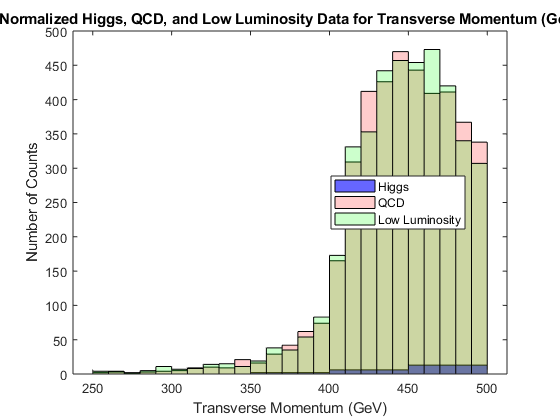

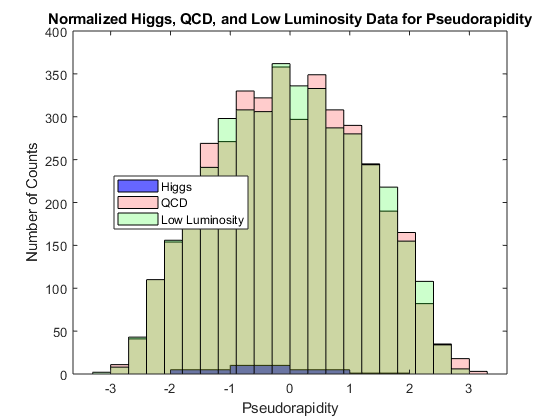

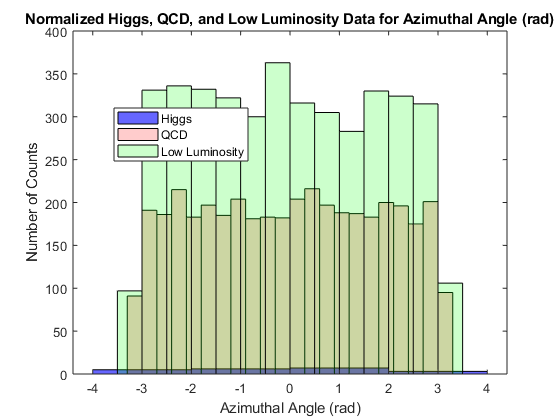

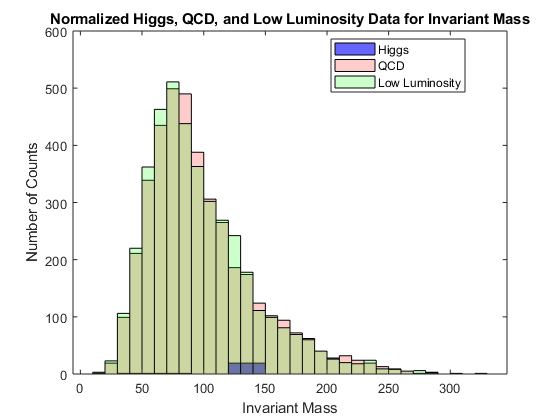

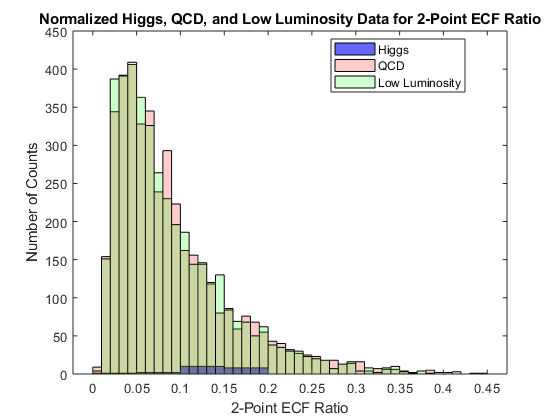

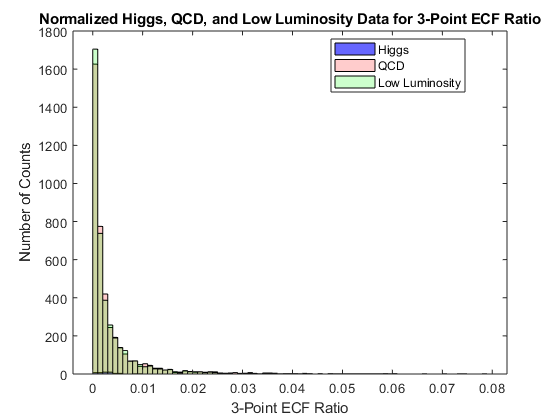

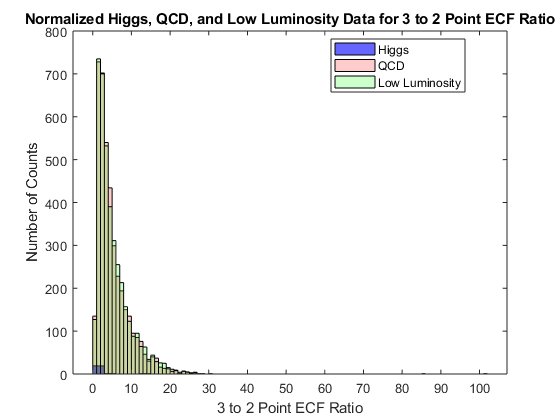

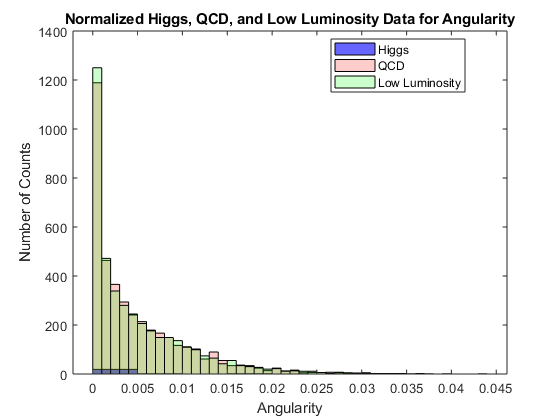

for i = 1:14
    
    figure(i+128)
    histogram(higgs_test(i,:),'FaceColor','blue'); 
    hold on 
    histogram(qcd_test(i,:),'FaceColor','red','FaceAlpha',0.2); 
    hold on 
    histogram(low_test(i,:),'FaceColor','green','FaceAlpha',0.2); 
    xlabel(VariableNames(i)); 
    ylabel('Number of Counts'); 
    title("Normalized Higgs, QCD, and Low Luminosity Data for " + VariableNames(i)); 
    legend('Higgs','QCD','Low Luminosity','Location','best');     
    
end 

**Nothing special or of note in these full-range distributions. Now going to check within the optimally selected ranges. **

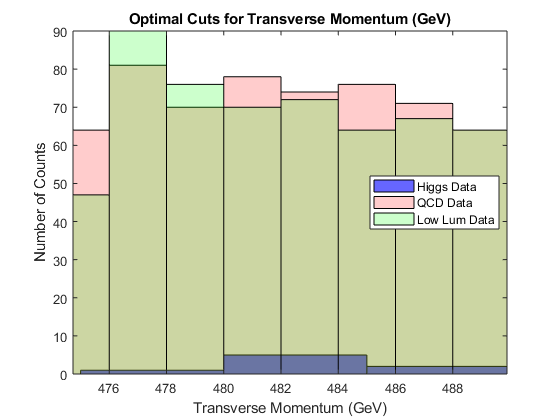

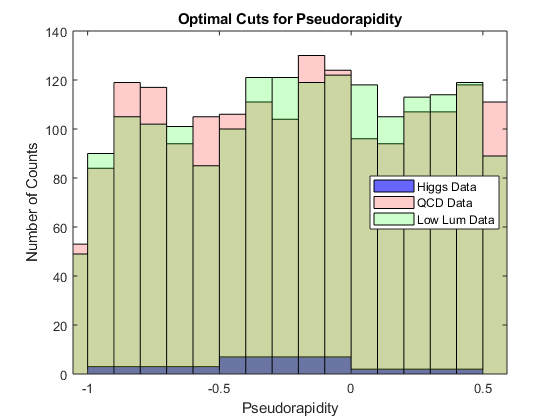

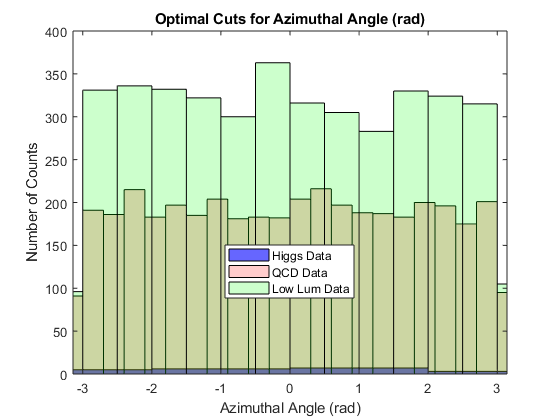

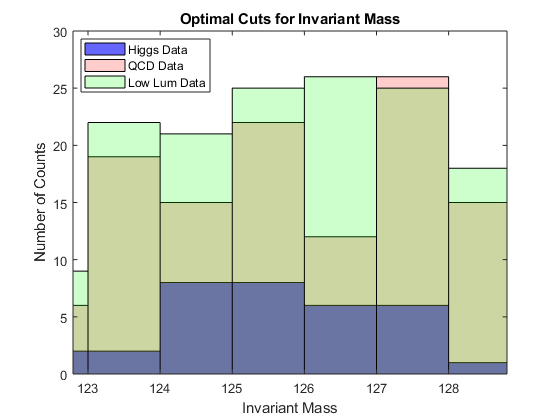

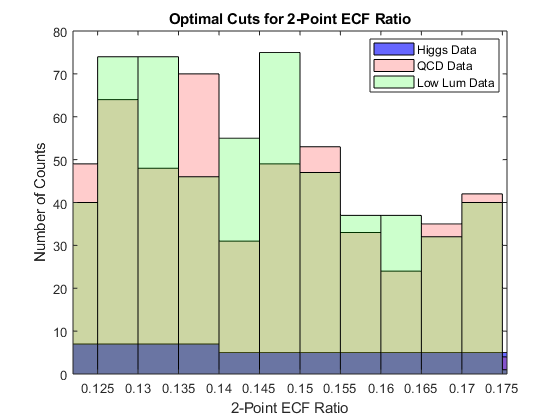

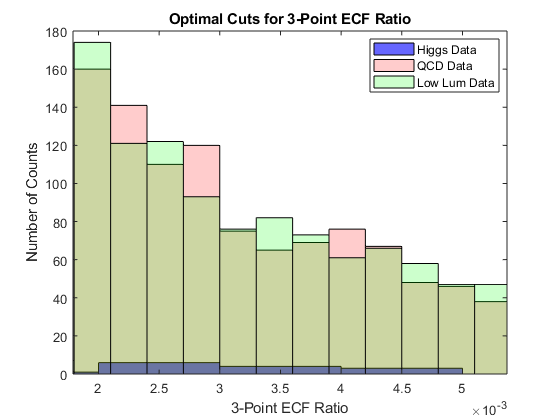

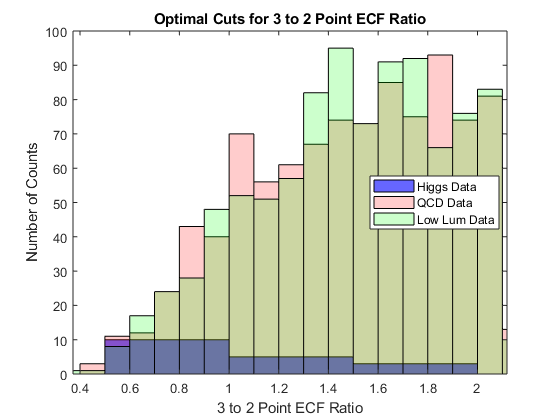

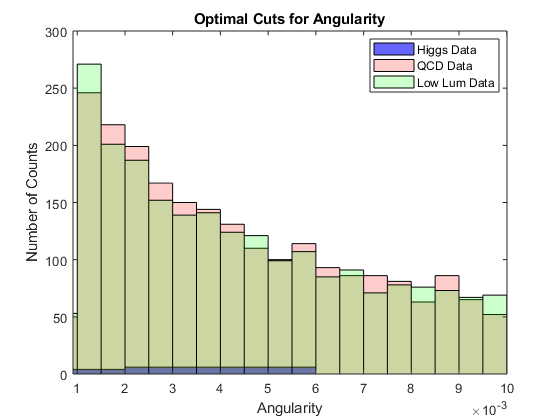

for j = 1:14
    
    higgs_cut = higgs_test(j,:); 
    qcd_cut = qcd_test(j,:); 
    low_lum_cut = low_test(j,:); 
    
    figure(142 + j)
    histogram(higgs_cut(higgs_cut > unordered_optimum_ratio{j,3} & higgs_cut <= unordered_optimum_ratio{j,4}),'FaceColor','blue')
    hold on 
    histogram(qcd_cut(qcd_cut > unordered_optimum_ratio{j,3} & qcd_cut <= unordered_optimum_ratio{j,4}),'FaceColor','red','FaceAlpha',0.2)
    hold on 
    histogram(low_lum_cut(low_lum_cut > unordered_optimum_ratio{j,3} & low_lum_cut <= unordered_optimum_ratio{j,4}),'FaceColor','green','FaceAlpha',0.2)
    
    xlim([unordered_optimum_ratio{j,3} unordered_optimum_ratio{j,4}]); 
    xlabel(VariableNames(j))
    ylabel('Number of Counts') 
    title("Optimal Cuts for " + VariableNames(j)); 
    legend('Higgs Data','QCD Data','Low Lum Data','Location','best'); 
    
end

**Like we saw for the high luminosity data, our low-luminosity experimental data that falls within the optimal cuts seems to closely resemble the sum of the signal and background distributions within this range. The table with the comparison of the significances between the training and experimental data is shown directly below. **

ratio_variableNames = {'Tested_Variable','Training_Set_SNR','Low_Lum_SNR','Percent_Diff'}; 
ratio_variableTypes = {'string','double','double','double'}; 
unordered_low_lum_ratio = table('Size',[14 4],'VariableTypes',ratio_variableTypes,'VariableNames',ratio_variableNames); 

for k = 1:14
    
    higgs_cut = higgs_test(k,:); 
    qcd_cut = qcd_test(k,:); 
    low_lum_cut = low_test(k,:); 
    
    num_higgs = numel(higgs_cut(higgs_cut > unordered_optimum_ratio{k,3} & higgs_cut <= unordered_optimum_ratio{k,4})); 
    num_qcd = numel(qcd_cut(qcd_cut > unordered_optimum_ratio{k,3} & qcd_cut <= unordered_optimum_ratio{k,4})); 
    num_low_lum = numel(low_lum_cut(low_lum_cut > unordered_optimum_ratio{k,3} & low_lum_cut <= unordered_optimum_ratio{k,4})); 
    
    unordered_low_lum_ratio{k,1} = VariableNames(k); 
    unordered_low_lum_ratio{k,2} = unordered_optimum_ratio{k,2}; 
    unordered_low_lum_ratio{k,3} = num_higgs/sqrt(num_low_lum); 
    unordered_low_lum_ratio{k,4} = (unordered_low_lum_ratio{k,3}-unordered_low_lum_ratio{k,2})/unordered_low_lum_ratio{k,2} * 100; 
    
end

low_lum_ratio = sortrows(unordered_low_lum_ratio,2,'descend'); 
disp(low_lum_ratio)

          Tested_Variable          Training_Set_SNR    Low_Lum_SNR    Percent_Diff
    ___________________________    ________________    ___________    ____________

    "Invariant Mass"                    2.8187            1.4069        -50.086   
    "t2"                                1.6573            1.0314        -37.765   
    "t3"                                1.6279           0.91717         -43.66   
    "t21"                               1.4965           0.75295        -49.687   
    "KtDeltaR"                          1.1465           0.51972        -54.671   
    "2-Point ECF Ratio"                 1.1443           0.71967        -37.109   
    "3 to 2 Point ECF Ratio"            1.0661           0.58247        -45.365   
    "3-Point ECF Ratio"                0.90637           0.43686        -51.801   
    "Transverse Momentum (GeV)"  

**The correlation between the observed and expected significances for the low luminosity data is much poorer than it was for the high luminosity data. I think this is an issue of scaling the datasets down to the expected yield. The low luminosity data expected yield should be the sum of the higgs and qcd (so 20,100), but the dataset itself was only 4060 points long.  In assuming that this 4060 was proportional to the total expected yield, and then scaling the size of the qcd and higgs training sets down to proportionally match this, I think I lost a significant degree of resolution in the data. This, I believe, is the primary source of error between the observed and expected significances. **

**Finally, we will try and compute the 95% upper confidence level of the signal yields, specifically for the low luminosity data. We will first compute this upper limit based on the training set data, and then do so for the low luminosity data, and then compare the two. **

higgs_avg = zeros(1,14); 
higgs_std = zeros(1,14); 
qcd_avg = zeros(1,14);
qcd_std = zeros(1,14); 
low_lum_avg = zeros(1,14);
low_lum_std = zeros(1,14); 

for i = 1:14 
    
    higgs_avg(i) = mean(higgs_test(i,:)); 
    qcd_avg(i) = mean(qcd_test(i,:)); 
    low_lum_avg(i) = mean(low_test(i,:)); 
    
    higgs_std(i) = std(higgs_test(i,:)); 
    qcd_std(i) = std(qcd_test(i,:)); 
    low_lum_std(i) = std(low_test(i,:)); 
    
end

ratio_variableNames = {'Tested_Variable','Upper_Confidence_Training','Upper_Confidence_Experiment','PercentDiff'}; 
ratio_variableTypes = {'string','double','double','double'}; 
low_lum_confidence = table('Size',[14 4],'VariableTypes',ratio_variableTypes,'VariableNames',ratio_variableNames); 

for j = 1:14 
    
    low_lum_confidence{j,1} = VariableNames(j); 
    low_lum_confidence{j,2} = higgs_avg(j) + 1.960 * higgs_std(j)/sqrt(length(higgs_test(j,:))); 
    low_lum_confidence{j,3} = low_lum_avg(j) + 1.960 * low_lum_std(j)/sqrt(length(low_test(j,:))); 
    low_lum_confidence{j,4} = (low_lum_confidence{j,3} - low_lum_confidence{j,2})/low_lum_confidence{j,2} * 100; 
    
end

disp(low_lum_confidence)

          Tested_Variable          Upper_Confidence_Training    Upper_Confidence_Experiment    PercentDiff
    ___________________________    _________________________    ___________________________    ___________

    "Transverse Momentum (GeV)"               466.69                        446.64               -4.2955  
    "Pseudorapidity"                         0.12208                      0.018099               -85.174  
    "Azimuthal Angle (rad)"                  0.64064                      0.029835               -95.343  
    "Invariant Mass"                          128.15                        98.485               -23.148  
    "2-Point ECF Ratio"                      0.14822                      0.091258               -38.432  
    "3-Point ECF Ratio"                    0.0037109                     0.0037124              0.040952  
    "3 

**We see a decent amount of confirmation between the expected and observed 95% upper confidence limits. This suggests that our selection of the optimal cuts was relatively well founded, since it has the ability to narrow in on a potential signal detection decently well. However, it looks like the upper confidence limit for the experimental data for some variables was lower than it was in the training data, which would imply that our optimal cuts actually performed better on the experimental data than they did on the training data. I am hesitant to agree with this conclusion, since our experimental data should by default have a little more spread and uncertainty than the training sets. Again, I think that the discrepancies between these observed and expected limits is due to the small size of the datasets themselves and the scaling we were forced to do to keep the expected yields proportional to one another. To check this, I will finally also compute these same confidence limit calculations, except this time will compare the training data to the high luminosity data. **

higgs_expected_yield = randi([1 100000],1,100); 
qcd_expected_yield = randi([1 100000],1,20000); 
high_expected_yield = randi([1 length(high_lum)],1,20100); 

higgs_test = higgs{:,higgs_expected_yield}; 
qcd_test = qcd{:,qcd_expected_yield}; 
high_test = high_lum(:,high_expected_yield); 

higgs_avg = zeros(1,14); 
higgs_std = zeros(1,14); 
qcd_avg = zeros(1,14);
qcd_std = zeros(1,14); 
high_lum_avg = zeros(1,14);
high_lum_std = zeros(1,14); 

for i = 1:14 
    
    higgs_avg(i) = mean(higgs_test(i,:)); 
    qcd_avg(i) = mean(qcd_test(i,:)); 
    high_lum_avg(i) = mean(high_test(i,:)); 
    
    higgs_std(i) = std(higgs_test(i,:)); 
    qcd_std(i) = std(qcd_test(i,:)); 
    high_lum_std(i) = std(high_test(i,:)); 
    
end

ratio_variableNames = {'Tested_Variable','Upper_Confidence_Training','Upper_Confidence_Experiment','PercentDiff'}; 
ratio_variableTypes = {'string','double','double','double'}; 
high_lum_confidence = table('Size',[14 4],'VariableTypes',ratio_variableTypes,'VariableNames',ratio_variableNames); 

for j = 1:14 
    
    high_lum_confidence{j,1} = VariableNames(j); 
    high_lum_confidence{j,2} = higgs_avg(j) + 1.960 * higgs_std(j)/sqrt(length(higgs_test(j,:))); 
    high_lum_confidence{j,3} = high_lum_avg(j) + 1.960 * high_lum_std(j)/sqrt(length(high_test(j,:))); 
    high_lum_confidence{j,4} = (high_lum_confidence{j,3} - high_lum_confidence{j,2})/high_lum_confidence{j,2} * 100; 
    
end

disp(high_lum_confidence)

          Tested_Variable          Upper_Confidence_Training    Upper_Confidence_Experiment    PercentDiff
    ___________________________    _________________________    ___________________________    ___________

    "Transverse Momentum (GeV)"               457.56                        446.44               -2.4297  
    "Pseudorapidity"                         0.24345                      0.016512               -93.218  
    "Azimuthal Angle (rad)"                  0.19115                      0.034362               -82.024  
    "Invariant Mass"                          118.17                        97.613               -17.393  
    "2-Point ECF Ratio"                      0.12962                      0.089875               -30.663  
    "3-Point ECF Ratio"                    0.0029611                     0.0035262                19.083  
    "3 

**While looking at the high luminosity data did reduce the error between the observed and expected upper confidence limits by an appreciable amount, the percentage differences are still too large to be considered insignificant. However, after inspecting both tables above and comparing them to the tables earlier describing the optimum thresholds, it looks like the variables with lower error between the confidence limits also happened to be the variables yielding the higher post-cut optimized signifances. This is some final, extra justification and indication that our optimum event selection thresholds were well chosen and did a good job of separating the majority of the signal and background data in our training sets. **

**EL FIN! **